He sacado la idea de usar los superpixeles de aquí: [02.05 An efficient framework for optic disk segmentation and classification of Glaucoma on fundus images.pdf](file:///C:/Users/marke/OneDrive/Escritorio/PBL%206/02.05%20An%20efficient%20framework%20for%20optic%20disk%20segmentation%20and%20classification%20of%20Glaucoma%20on%20fundus%20images.pdf)

clc; clear all; close all;

img_path = fullfile('Codes','OD_circle_SQ_9_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

RGB = imread(string(fullfile(img_path, T{373,1})));%Aquí elijes la imagen

superpixelQuantity=400;
[L,N] = superpixels(RGB,superpixelQuantity, "NumIterations",150,"Compactness",1);

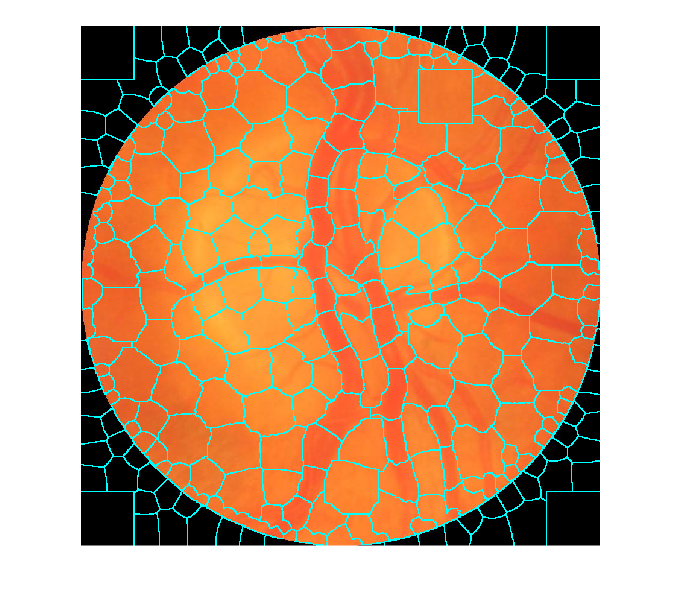

figure;
BW = boundarymask(L);
figure;
imshow(imoverlay(RGB,BW,'cyan'),'InitialMagnification',67);

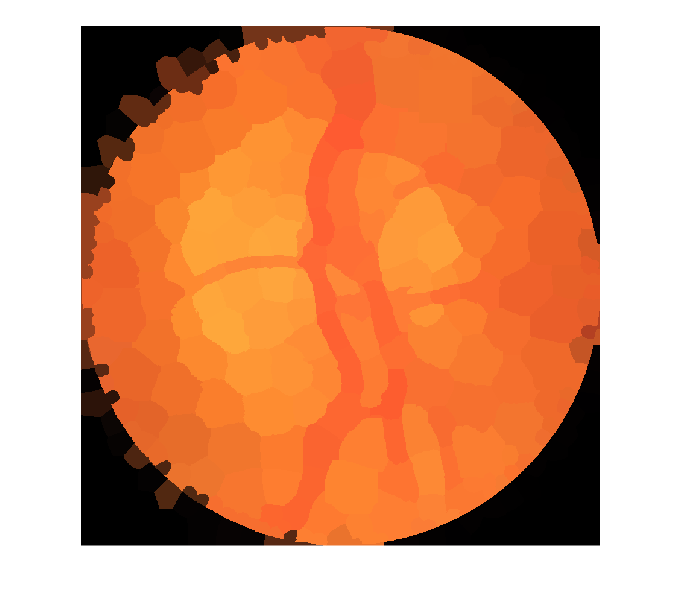

outputImage = zeros(size(RGB),'like',RGB);
idx = label2idx(L);
numRows = size(RGB,1);
numCols = size(RGB,2);
for labelVal = 1:N
    redIdx = idx{labelVal};
    greenIdx = idx{labelVal}+numRows*numCols;
    blueIdx = idx{labelVal}+2*numRows*numCols;
    outputImage(redIdx) = mean(RGB(redIdx));
    outputImage(greenIdx) = mean(RGB(greenIdx));
    outputImage(blueIdx) = mean(RGB(blueIdx));
end    

figure
imshow(outputImage,'InitialMagnification',67)